Construir una función a partir de componentes exponenciales complejos

Se representará la siguiente función:


$$x(n)=3(0.2)^n-0.2(-0.1)^n+0.1(\cos(\frac{\pi}{3})+\jmath\sin(\frac{\pi}{3}))^n+0.1(cos(\frac{\pi}{3})-\jmath\sin(\frac{\pi}{3}))^nu(n)$$


Advierta el uso del operador para elevar a la potencia n

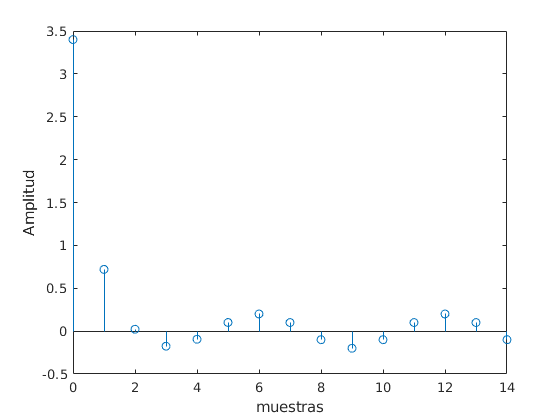

n=0:14;
xn=3*(0.2.^n)-0.2*(-0.1.^n)+0.1*((cos(pi/3)+1i*sin(pi/3)).^n)+0.1*((cos(pi/3)-1i*sin(pi/3)).^n);
figure
stem(n,xn)
xlabel('muestras')
ylabel('Amplitud')

Variación de parámetros de la función compuesta

A1=2

A1 = 2

p1=0.3

p1 = 0.3000

A2=-1.1

A2 = -1.1000

p2=-0.7

p2 = -0.7000

A3=0.2

A3 = 0.2000

f1=0.6

f1 = 0.6000

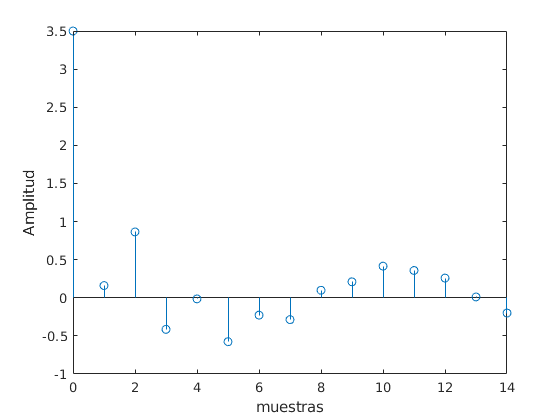

xnv=A1*(p1.^n)-A2*(p2.^n)+A3*((cos(f1)+1i*sin(f1)).^n)+A3*((cos(f1)-1i*sin(f1)).^n); 
figure
stem(n,xnv)
xlabel('muestras')
ylabel('Amplitud')

Observe la ubicación de los número complejos que hacen parte de las funciones que se están combinando (debe tener el archivo circulo.m en la misma carpeta de este ejemplo)

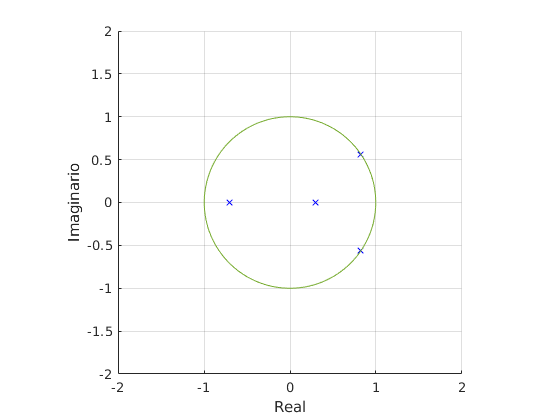

z1=(cos(f1)+1i*sin(f1));
z2=(cos(f1)-1i*sin(f1));
figure
hold on
plot(p1,0,'bx')
plot(p2,0,'bx')
plot(z1,'bx')
plot(z2,'bx')
circulo(0,0,1)
grid on
axis equal
xlabel('Real')
ylabel('Imaginario')
xlim([-2 2])
ylim([-2 2])
hold off